% Data Upload 
dati = readtable('SP500_2022.xlsx');

df = dati(:, {'time', 'AAPL_OQ'});

% Convert time to a Datetime Format 
df.time = datetime(df.time)

df = 5638×2 table
       time        AAPL_OQ
    ___________    _______

    03-Jan-2000    0.99944
    04-Jan-2000    0.91518
    05-Jan-2000    0.92857
    06-Jan-2000    0.84821
    07-Jan-2000    0.88839
    10-Jan-2000    0.87277
    11-Jan-2000    0.82812
    12-Jan-2000    0.77846
    13-Jan-2000    0.86384
    14-Jan-2000    0.89676
    17-Jan-2000    0.89676
    18-Jan-2000    0.92801
    19-Jan-2000    0.95145
    20-Jan-2000     1.0134
    21-Jan-2000    0.99386
    24-Jan-2000    0.94866


% Return Trend 
rt = price2ret(df.AAPL_OQ)

rt =    -0.0881
    0.0145
   -0.0905
    0.0463
   -0.0177
   -0.0525
   -0.0618
    0.1041
    0.0374
         0


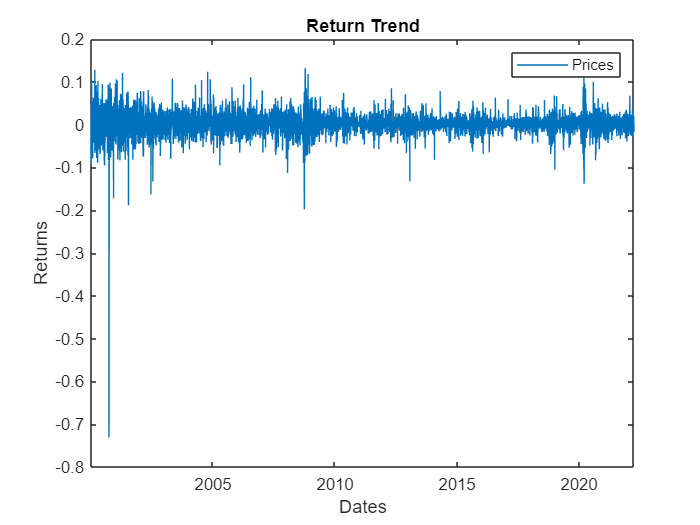

figure()
plot(df.time(2:end), rt)
ylabel('Returns')
xlabel('Dates')
legend('Prices')
title('Return Trend')

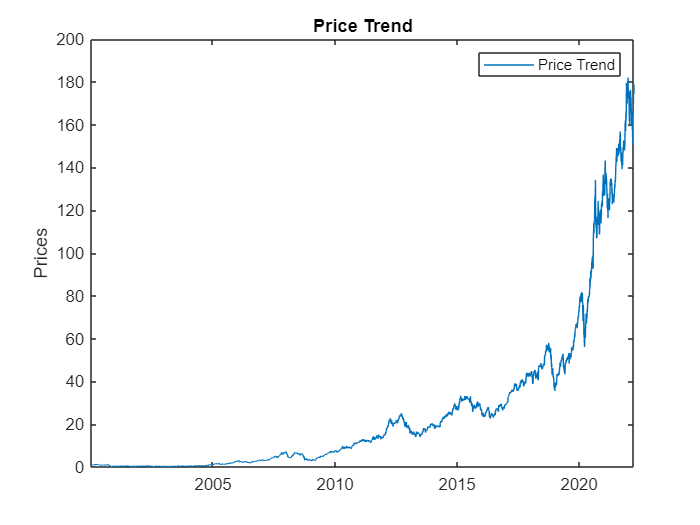


% Price Trend
figure()
plot(df.time, df.AAPL_OQ)
ylabel('Prices')
legend('Price Trend')
title('Price Trend')

% Garch Models
Md1 = garch(1,1);
Md1.Distribution = 't';
[EstMd1_garch,EstParamCov,logL,info]=estimate(Md1,rt);

 
    GARCH(1,1) Conditional Variance Model (t Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    4.216e-06      1.111e-06        3.7947       0.0001478
    GARCH{1}      0.92628      0.0065457        141.51               0
    ARCH{1}      0.070954      0.0070994        9.9943      1.6144e-23
    DoF            4.7723        0.28727        16.612      5.6824e-62



summarize(EstMd1_garch)

 
   GARCH(1,1) Conditional Variance Model (t Distribution)
 
    Effective Sample Size: 5637
    Number of Estimated Parameters: 4
    LogLikelihood: 13947.5
    AIC: -27887.1
    BIC: -27860.5
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    4.216e-06      1.111e-06        3.7947       0.0001478
    GARCH{1}      0.92628      0.0065457        141.51               0
    ARCH{1}      0.070954      0.0070994        9.9943      1.6144e-23
    DoF            4.7723        0.28727        16.612      5.6824e-62

 


Md2 = garch(1,1);
Md2.Distribution = 'Gaussian';
[EstMd2_garch,EstParamCov,logL,info]=estimate(Md2,rt);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    8.2604e-06     4.6346e-07        17.823      4.6467e-71
    GARCH{1}       0.89431       0.002947        303.46               0
    ARCH{1}       0.099665      0.0021921        45.466               0



summarize(EstMd2_garch)

 
   GARCH(1,1) Conditional Variance Model (Gaussian Distribution)
 
    Effective Sample Size: 5637
    Number of Estimated Parameters: 3
    LogLikelihood: 13601.8
    AIC: -27197.5
    BIC: -27177.6
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    8.2604e-06     4.6346e-07        17.823      4.6467e-71
    GARCH{1}       0.89431       0.002947        303.46               0
    ARCH{1}       0.099665      0.0021921        45.466               0

 


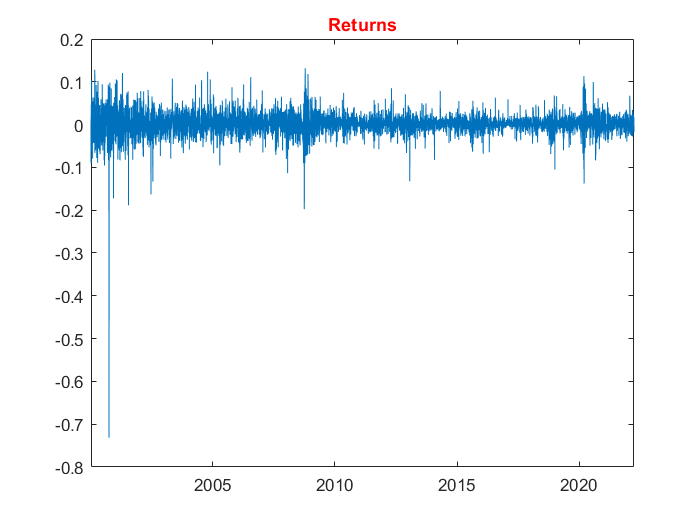

% Leverage Control
V_cond = infer(EstMd1_garch,rt);
Devst_cond = sqrt(V_cond);

figure()
plot(df.time(2:end),rt)
title('Returns','color','red')

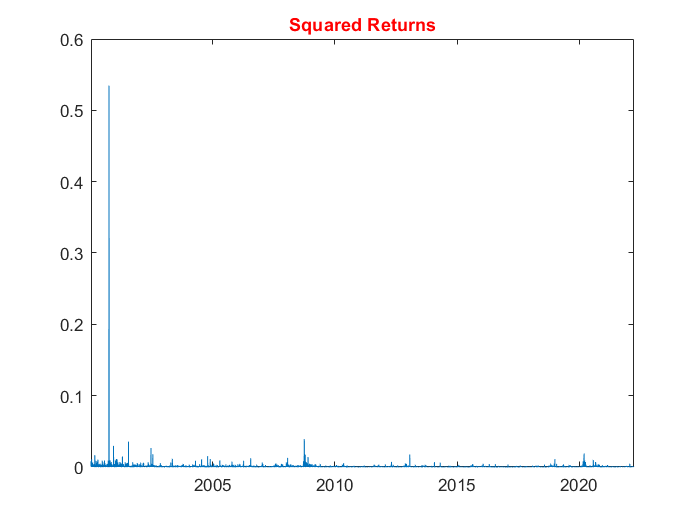


figure()
plot(df.time(2:end),rt.^2)
title('Squared Returns','color','red')

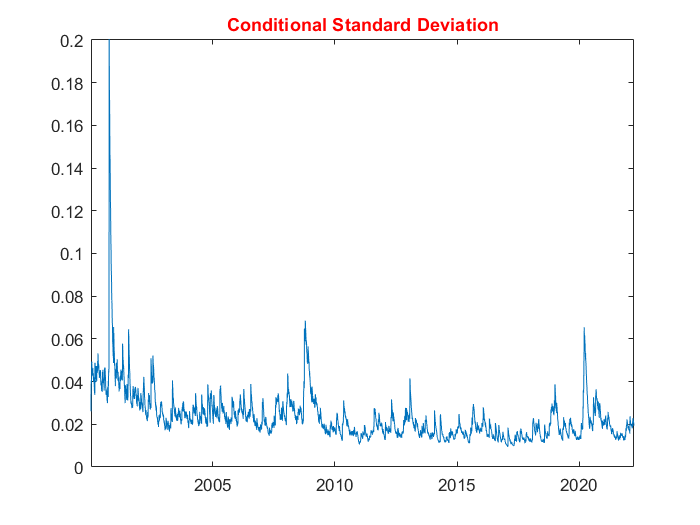


figure()
plot(df.time(2:end), Devst_cond)
title('Conditional Standard Deviation','color','red')

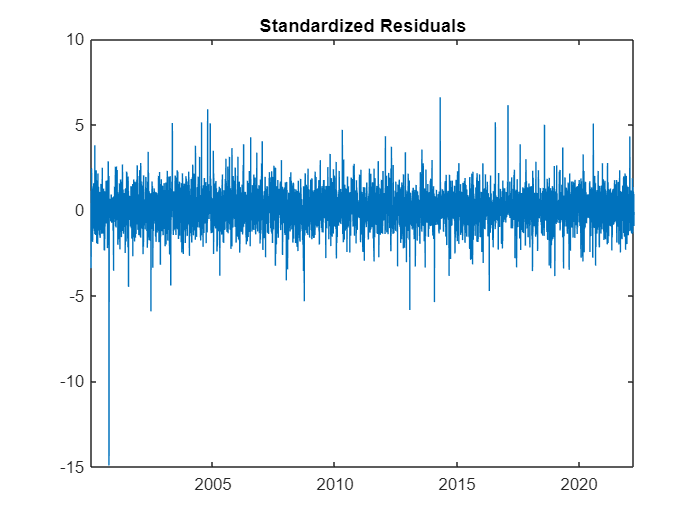

% Standardized Residuals
restd = rt./Devst_cond;
plot(df.time(2:end), restd)
title('Standardized Residuals')

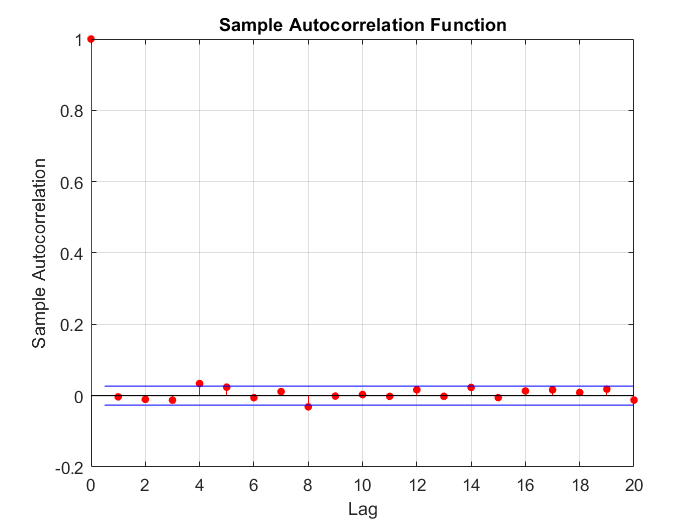

autocorr(restd) 

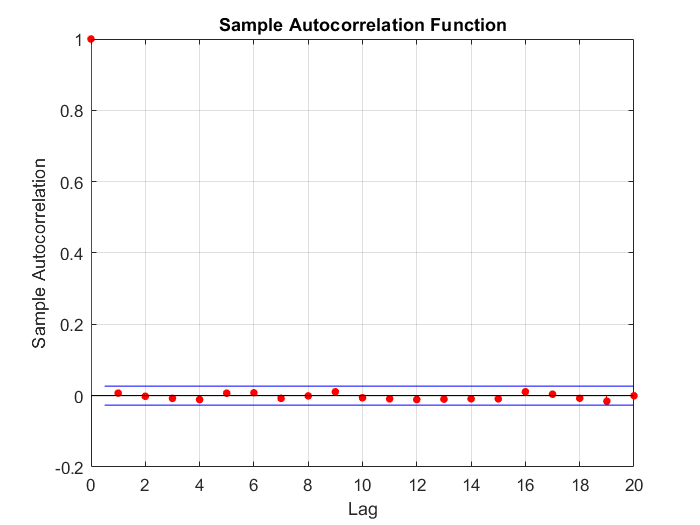

autocorr(restd.^2)

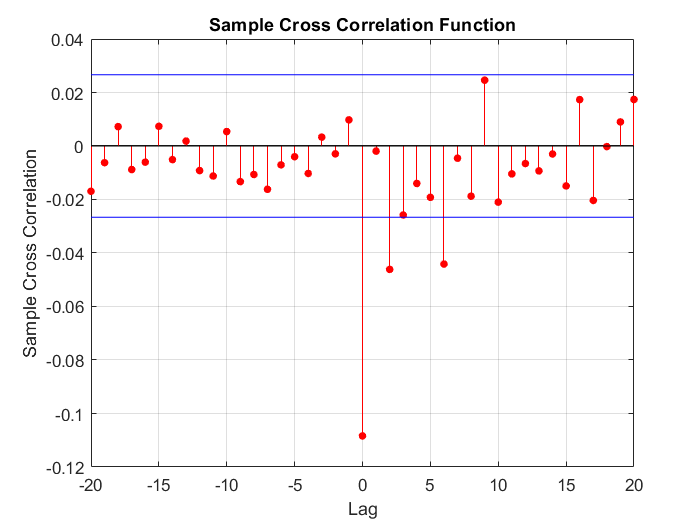

crosscorr(restd, restd.^2)

%% GJR-GARCH Models
Mdl = gjr(1,1);
Mdl.Distribution = 't';
[EstMdl_gjr, EstParamCov,logL,info] = estimate(Mdl,rt);

 
    GJR(1,1) Conditional Variance Model (t Distribution):
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant       7.0814e-06     1.1312e-06        6.2602      3.8445e-10
    GARCH{1}          0.90317      0.0079278        113.92               0
    ARCH{1}          0.053353      0.0087403        6.1042      1.0331e-09
    Leverage{1}      0.083459       0.014628        5.7054      1.1604e-08
    DoF                4.8328        0.29593        16.331      5.9428e-60



summarize(EstMdl_gjr)

 
   GJR(1,1) Conditional Variance Model (t Distribution)
 
    Effective Sample Size: 5637
    Number of Estimated Parameters: 5
    LogLikelihood: 13962.9
    AIC: -27915.8
    BIC: -27882.6
 
                     Value       StandardError    TStatistic      PValue  
                   __________    _____________    __________    __________

    Constant       7.0814e-06     1.1312e-06        6.2602      3.8445e-10
    GARCH{1}          0.90317      0.0079278        113.92               0
    ARCH{1}          0.053353      0.0087403        6.1042      1.0331e-09
    Leverage{1}      0.083459       0.014628        5.7054      1.1604e-08
    DoF                4.8328        0.29593        16.331      5.9428e-60

 


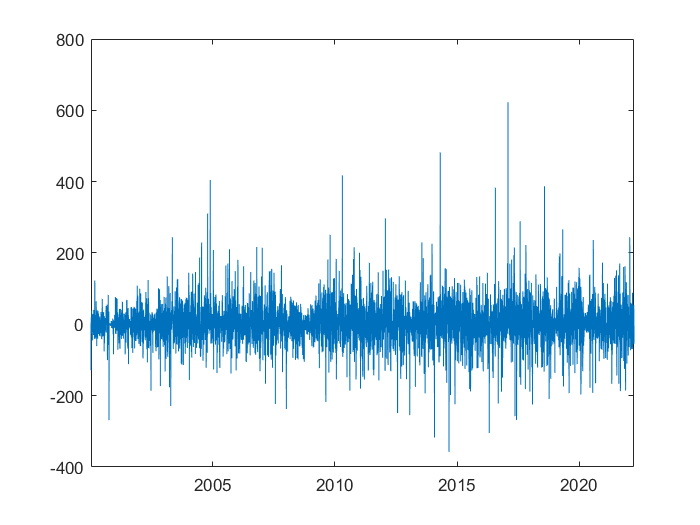

% Standardized Residuals
Vcond_gjr = infer(EstMdl_gjr,rt);
Devstd_cond_gjr = sqrt(Vcond_gjr);
restd_gjr = rt./Vcond_gjr;
figure('Name','Standardizer Residuals')
plot(df.time(2:end),restd_gjr)

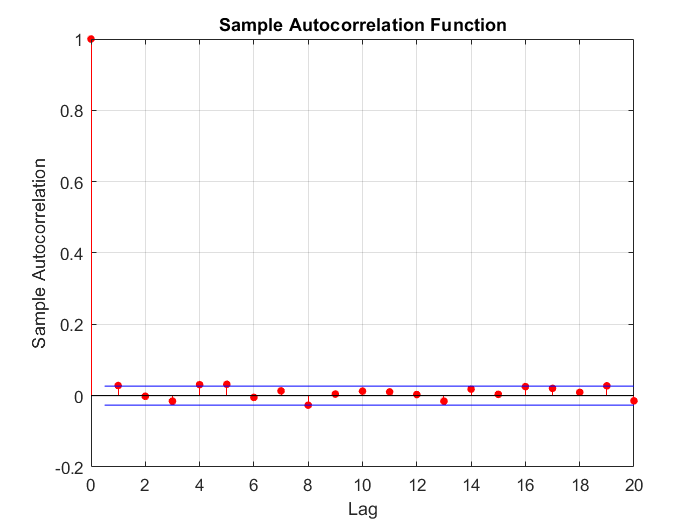


% Autocorrelation Function
autocorr(restd_gjr) 

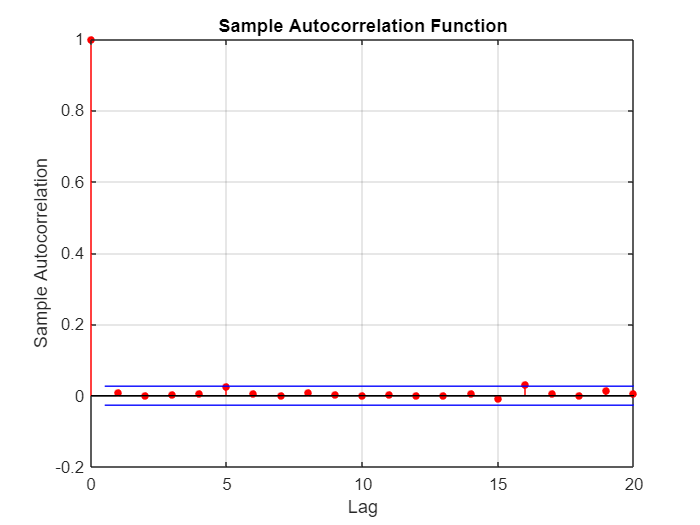

autocorr(restd_gjr.^2)

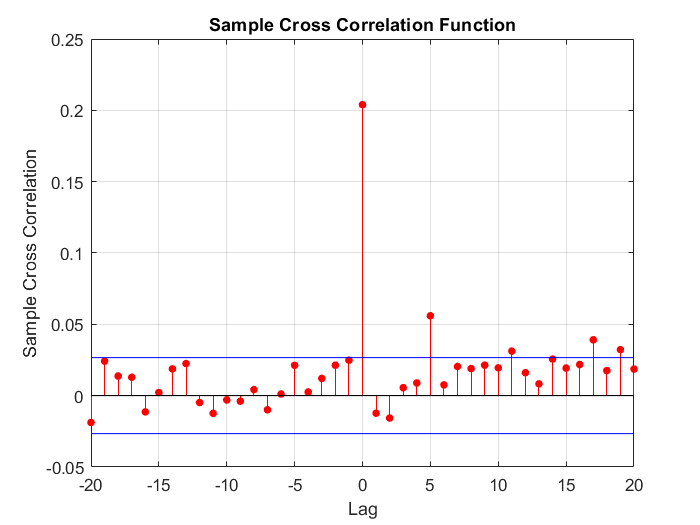

% Cross-Correlation Function
crosscorr(restd_gjr,restd_gjr.^2)

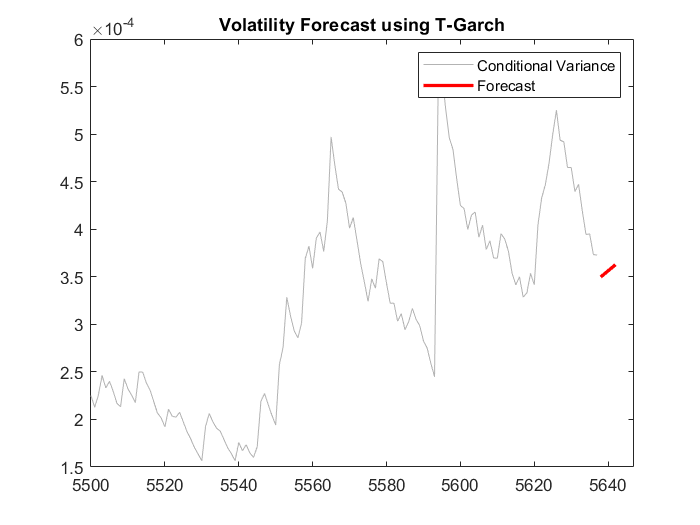

% Volatility Forecast
L = 5;
l = length(rt);
for1 = forecast(EstMd1_garch,L,'Y0',rt);

figure()
plot(V_cond,'color',[.7,.7,.7])
xlim([5500 l+L+5]);
hold on
plot(l+1:l+L,for1,'r','LineWidth',2);
legend('Conditional Variance','Forecast')
title('Volatility Forecast using T-Garch')
hold off

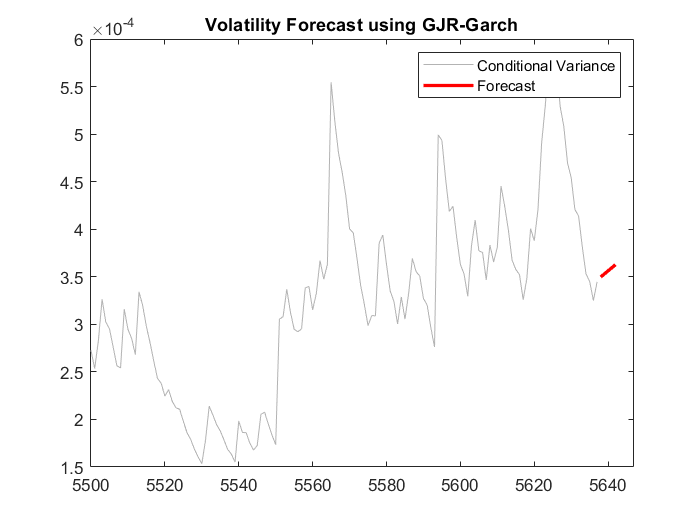

figure()
plot(Vcond_gjr,'color',[.7,.7,.7])
xlim([5500 l+L+5]);
hold on
plot(l+1:l+L,for1,'r','LineWidth',2);
legend('Conditional Variance','Forecast')
title('Volatility Forecast using GJR-Garch')
hold off